# Detect Circles from IP Camera Using Image Processing Toolbox

This example shows how to use the images captured by an IP camera to perform circle detection using the Image Processing Toolbox™. Detect coins in the field of view of the IP camera, and create an outline around each of them in real time.

## Create a Connection to your IP Camera

Create a connection to the IP camera using the `ipcam` function.

camera = ipcam('http://172.31.214.164:8080/video');

Use the `preview` function to open a window with a live stream from your IP camera. Adjust the positioning of your camera as necessary to capture the field of view that you want. In this example, the camera is capturing all the coins from directly above, to reduce distortion of the circular shape of the coins.

preview(camera)

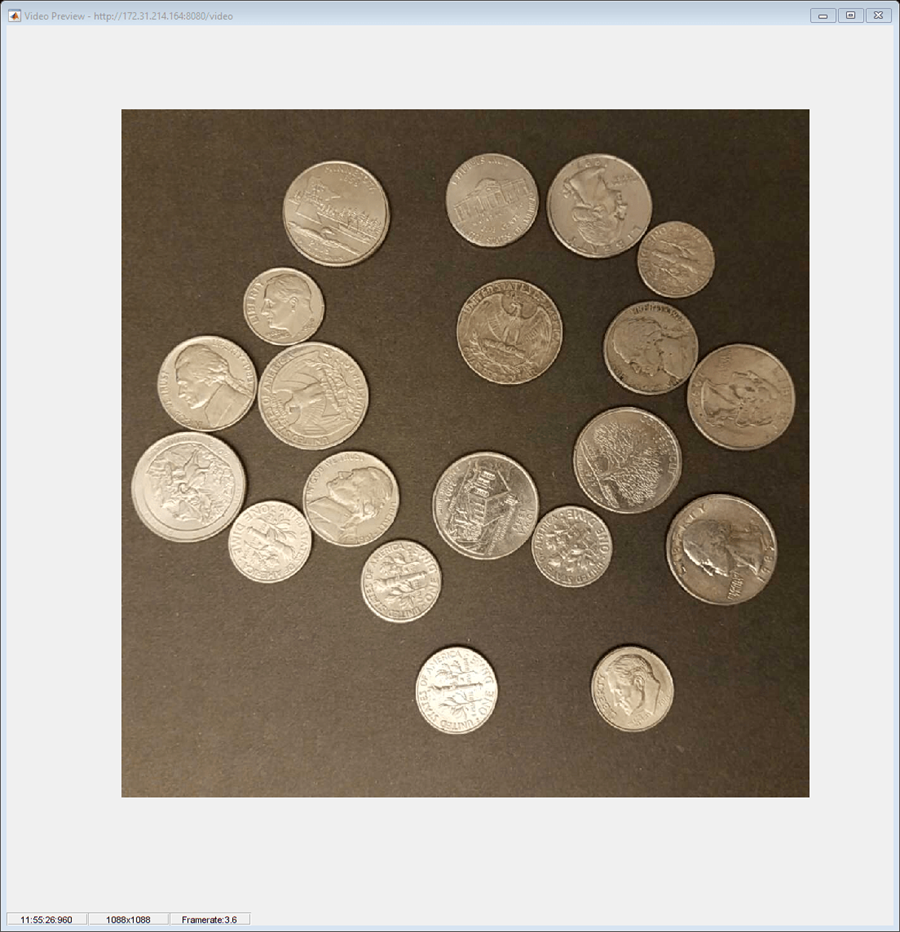

## Acquire an Image to Detect Circles

Start by capturing a single image and applying the circle detection function to it.

Capture a still image from the IP camera stream by using `snapshot`. For this example, adjust the settings for your IP camera so that the field of view is a square. Resize the image to 250 pixels by 250 pixels. This size makes the image processing faster. Preview the image in a figure window. All the coins should be in the image.

picture = snapshot(camera);
picture = imresize(picture,[250,250]);
image(picture);

The circle detection function, `imfindcircles`, requires a radius range to search for circles. Use `imdistline` to create an interactive tool in the figure window for estimating circle radii.

d = imdistline;

In this example, the coin radii range from approximately 10 to 20 pixels. Delete the tool once you are finished with it.

delete(d)

Run the circle detection function with these parameters. Then, draw outlines of the detected circles on your image.

[centers,radii] = imfindcircles(picture,[10 20]);
h = viscircles(centers,radii);

You can adjust the parameters of the function if all the circles were not detected. See `imfindcircles` for a list of additional input arguments to adjust the search parameters. In this example, the threshold of confidence for identifying a circle is lowered by setting the 'Sensitivity' parameter to 0.9 from the default 0.85.

[centers,radii] = imfindcircles(picture,[10 20],'Sensitivity',0.9);
h = viscircles(centers,radii);

All the coins in the still image are now clearly marked.

## Create a Loop to Detect Circles in Real Time

Run the circle detection function inside a loop, using the same parameters from the still image. The number of frames captured is set to 500 and the frame number is labeled in the figure window.

nframes = 0;
while (nframes<500)   
    picture = snapshot(camera);
    picture = imresize(picture,[250,250]);
    [centers,radii] = imfindcircles(picture,[10 20],'Sensitivity',0.9);
    image(picture);
    h = viscircles(centers,radii);
    title(string(nframes))
    nframes = nframes + 1;
end

You can move coins in and out of the field of view to see how the circle detection performs in real time.

*Copyright 2018 The MathWorks, Inc.*